# Hvammsvirkjun - Vatsborðsstýring Hagalóns

# Inngangur

Þetta forrit er notað til að herma vatnsborðsstýringu Hagalóns í Hvammsvirkjun. 

PI stýring er notuð til að regla lokur virkjunarinnar þ.a. vatnshæð er haldið í 116m y.s. í Hagalóni. 

# Nafnakerfi ("Nomenclature")

- P.O.: Percent Overshoot

- $T_s$: Settling Time

- $T_p$: Maximum Percent Overshoot

- MVs (Manipulated Variables): $u = D$

- CVs (Controlled Variables): 

- SP: Set Point

- PV: Process Variable

# Blokk mynd ("Block Diagram")

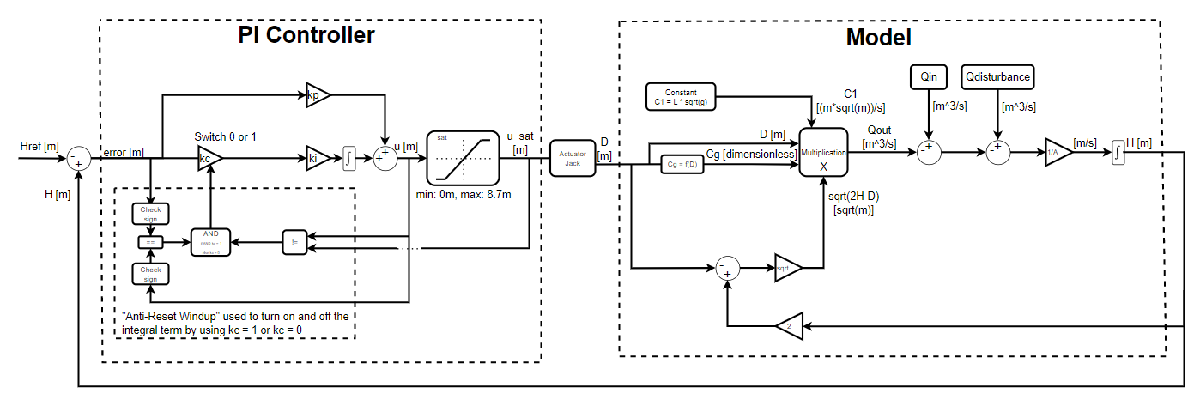 

# Modeling

Flæðið út um geiraloku er gefið með 


$$Q = \frac{dV}{dt} = C_g(D) D L\sqrt{2gH_g}  \qquad \quad (1)$$
 

þar sem $C_g$ er fall af $D$ og


$$H_g = H - \frac{D}{2} \qquad \quad (2)$$


Með því að setja jöfnu (2) inn í jöfnu (1) þá fæst


$$Q = \frac{dV}{dt} = C_g(D) D L \sqrt{g} \sqrt{2H-D} \qquad \quad (3)$$


Þegar allir fastar eru settir saman í eitt þá fæst 


$$C_1 = C_g(D) L \sqrt{9.82} \qquad \quad (4)$$
 

Einfaldað flæði út um geiraloku er því gefið með 


$$Q= C_1 D \sqrt{2H-D} \qquad \quad (5)$$


Hægt er að herma Hagalón sem vatnstank. Hlutfallsbreyting á vatnshæð í vatnstanki er gefin með 


$$\dot H = \frac{1}{A} (Q_{in} - Q_{out} - Q_D) \qquad \quad (6)$$


Hægt er að heilda vatnshæðarbreytinguna í (6) og fá þannig hæðina með samfelldu heilduninni


$$H = \int_0^t \dot H(\tau) \,d\tau \qquad \quad (7)$$
           

sem hægt er að reikna í stakrænum tíma með Riemann summunni


$$H = \sum_{i=0}^t  \dot H(t) \cdot \Delta t \qquad \quad (8)$$


"Error" fyrir PI stýringuna er hægt að reikna með


$$e(t) = SP - PV \qquad \quad (9.1)$$


Þar sem lokurnar eru ekki staðsettar inn í lónið, heldur út úr lóninu, þá er "error" merkið gefið með


$$e(t) = PV - SP  \qquad \qquad (9.2)$$


þar sem $PV$ er "the process variable (the measured water height)" og $SP$ er "the set-point (the reference value)". PI stýringin er því gefin með


$$P(t) = k_p \cdot e(t) \qquad \quad (10)\\
I(t) = k_I \cdot \int e(t) \, dt \qquad \quad (11)$$


þar sem $k_p$ og $k_I$ eru mögnunar fastar fyrir sitthvorn liðinn, mögnunarlið og heildunarlið. Útgangur PI stýringarinnar er reiknaður með


$$u(t) = u_{bias} + P(t)\cdot I(t) \qquad \quad (12)$$


Hægt er að reikna $K_p$ og $K_I$ liðina m.t.t. "controller gain $K_c$" og heildunar "reset time $\tau_i$"


$$K_p = K_c \qquad \qquad (13)$$



$$K_I = \frac{K_c}{\tau_i} \qquad \qquad (14)$$


$u_{bias}$ liðurinn er fasti sem er venjulega valinn sem $u(t)$ þegar stýringunni er fyrst skipt yfir úr "manual" yfir í "automatic mode". Þetta gefur "bumpless transfer" ef error merkið er núll þegar stýringin er sett í virka stöðu ("on"). Gildið á $K_c$ er margföldun á "proportional error" og "integral term", því hærra sem gildið er því meira "aggressive" er svörun reglisins við "error" sem myndast frá "SP - set point" gildinu. Heildunarliðurinn $\tau_i$ (einnig nefnt "integral reset time") verður að vera jákvæður og hefur eininguna tíma. Þegar $\tau_i$ verður minna og minna, þá verður heildunarliðurinn stærri og stærri vegna þess að $\tau_i$ er í nefnara deilingarinnar.

- Tilvitnun: [https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative) 

# Flipaloka

Flæði út um flipaloku er lýst með


$$Q_{f,out} = 1.8 \cdot H^{3/2}*b$$


Þar sem $b=20m$ er breidd lokunnar.

# Seiðaloka

Flæði út um seiðaloku er lýst með


$$Q_{out} = \frac{dV}{dt} = C_p(D) C_2 D \sqrt{2H-D}$$


þar sem $C_2 = L\sqrt{g}$. Til að byrja með eru dregnir $10 m^3/s$ frá flæði um seiðalokuna vegna takmarkana á flæði í gegn um þröskuld, þ.a.


$$Q_{out,new} = Q_{out} - 10 \frac{m^3}{s}$$


Flæði í gegn um þröskuld er gefið með


$$Q_{out} = C_d L_{eff} H^{1,5}$$


þar sem $L_{eff} = 19m$ og $C_d = 1.518$.

# Stakræn heildun ("Discrete Integration")

Trapezoidal rule approximation (Discrete Intregral):

- $\int e(t) dt$ er flatarmál undir kúrvu

- Flatarmálið er nálgað með "the trapezoidal rule":


$$int = \frac{e(t) + e(t-1)}{2} T_s$$


eða 


$$int = \frac{T_s}{2} (1+z^{-1}) e(t)$$


- Tilvitnun: [https://www.youtube.com/watch?v=LcsaEF-i1j4](https://www.youtube.com/watch?v=LcsaEF-i1j4) 

- Í samfelldum tíma, heildunarliðurinn í PID hefur 2 núll og 1 pól í núllpunkti, þ.e. fyrir miðju.

- Í stakrænum tíma, heildunarliðurinn í PID hefur 2 núll og 1 pól í 1 ( þ.e. á einingarhringnum)

# Opnun geiraloku ("Radial Gate Opening")

Það á að taka 1 mínútu að opna geiraloku um 1 meter. 


$$\frac{1m}{60s} = \frac{8.7m}{x} \qquad \qquad (13)$$



$$x = \frac{8.7 \cdot 60}{1} = 522s \qquad \qquad (14)$$


Til að finna jöfnu fyrir hægvirkni lokunnar, þá er hægt að nota "feedback" þ.a.


$$error_{gate}(i) = u_{sat}(i) - D(i) \qquad \qquad (15)$$


og síðan hægt að nota ramp fall, þ.a. jafna línu er gefin með


$$y = ax + b \qquad \qquad (16)$$


þar sem hallatalan er gefin með


$$a = \frac{y_2-y_1}{x_2-x_1} \qquad \qquad (17)$$


og síðan er "bias/offset" gefið með $b = 0$ m.t.t. geiralokunnar og $x(i) = error_{gate}(i)$. Jafna lokunnar er því gefin með


$$D(i) = D(i-1) + ax+b\\
\quad \quad \qquad = D(i-1) + \frac{8.7}{522} error_{sat}(i) \\
\quad \quad \qquad = D(i-1) + \frac{8.7}{522} \big(u_{sat}(i) - D(i)\big) \qquad \qquad (18)$$


**(það er möguleiki að **$dt$** eigi að vera margfaldað við jöfnu (18), en ekki alveg viss eins og er)**

Hallatalan er gefin með


$$a = \frac{8.7 - 0}{522 - 0} = \frac{1}{60} = 0.0167 \qquad \qquad (19)$$


# Flatarmál Hagalóns ("Area of the Reservoir")

Tveir punktar eru gefnir sem:

 
$$p_1 = (116,3.8) = (x_1,y_1)  \qquad [m\,\,a.s.l.,km^2] \\
p_2 = (117,4.3) = (x_2,y_2)$$


Hallatalan er 


$$m = \frac{y_2-y_1}{x_2-x_1} = \frac{4.3-3.8}{117-116} = 0.5$$


Jafna línu er


$$y-y_1 = m(x-x_1)$$


þar sem það er mögulegt að nota annað hvort $p_1$ eða $p_2$.

Flatarmál sem fall af hæð er gefið með


$$y-3.8 = 0.5(x-116)$$


leysa fyrir $y$ gefur


$$A(H) = 0.5H - 54.2$$


**Minnispunktur:** **það er ekki nauðsynlegt að líta á flatarmálið sem fall af breytu vegna þess að við erum að vinna í kring um 116m yfir sjávarmáli, þ.a. flatarmálið er ekkert að breytast mikið.**

# Nyquist Sampling Theory - Mjög mikilvægt!

Það er mjög mikilvægt að stilla hermunartímann þ.a. hann sé a.m.k. tvisvar sinnum söfnunartíminn til að koma í veg fyrir "aliasing". Ef þetta er ekki gert þá virkar hermunin ekki eins og hún á að gera.

Söfnunartíðnin $F_s$ verður að vera a.m.k. tvisvar sinnum tíðnin $F$ til að koma í veg fyrir "aliasing"


$$t_s = \frac{1}{F_s} = dt = T_s$$



$$t = \frac{1}{F}$$


Raunverulegt tilfelli: Þegar hermunartíminn var stilltur á 1 dag, þá byrjaði "aliasing" að hafa mjög mikil áhrif á hermunina. En þegar hermunartímanum var breytt í 4 daga, þá urðu allar niðurstöður eðlilegar.

Dæmi: Ef ferlinu er safnað frá 0 til 20, þá þarf að deila "the samples" í a.m.k. $2\cdot20+1 = 41$ hluta.

# Integral Anti-Reset Windup (AWR)

Útgangur stýringarinnar fer í mettun í min og max opnun á geiraloku, $D = [0:8.7]m$.

- C code: [https://github.com/BanaanKiamanesh/Anti-Windup-PID-Controller/blob/main/PID.cpp](https://github.com/BanaanKiamanesh/Anti-Windup-PID-Controller/blob/main/PID.cpp)

Anti-Reset Windup aðgerðir:

- Clamping

- Forward Clamping

Ekki nota þessa linka sem tilvitnanir:

- Link to image of clamping: [https://www.mathworks.com/videos/understanding-pid-control-part-2-expanding-beyond-a-simple-integral-1528310418260.html](https://www.mathworks.com/videos/understanding-pid-control-part-2-expanding-beyond-a-simple-integral-1528310418260.html) 

- Another useful link for clamping: [https://www.youtube.com/watch?v=UMit8mVCJ_I](https://www.youtube.com/watch?v=UMit8mVCJ_I) 

- Link to image of back-calculation: [https://www.youtube.com/watch?v=ATmoujzc6-w](https://www.youtube.com/watch?v=ATmoujzc6-w) 

- Anti-windup Schemes for Proportional Integral and Proportional Resonant Controller (Anirban Ghoshal and Vinod John )

Nota þessa linka sem tilvitnanir (virkar):

- [https://www.youtube.com/watch?v=tSOMSxGLzQo](https://www.youtube.com/watch?v=tSOMSxGLzQo) 

- [https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative) 

- [https://github.com/APMonitor/pdc/blob/master/pid_widget.ipynb](https://github.com/APMonitor/pdc/blob/master/pid_widget.ipynb) 

# Hlutfall breytingar á hæð ("Rate of Change of the Height")

- Rúmmál kassalaga vatnstanks: $V=l\cdot w\cdot h$    (For Cylinder tank it would be: $V = \pi r^2 h$)

Diffrum rúmmálsjöfnuna:


$$\frac{dV}{dt} = \frac{d}{dt} \left(l\cdot w\cdot h\right)$$


Finnum $\frac{dh}{dt}$ og g.r.f. að $w = l$:


$$\frac{dV}{dt} = \frac{dl^2}{dt} \cdot \frac{dh}{dt}$$



$$\frac{dh}{dt} = \frac{\frac{dV}{dt}}{\frac{dl^2}{dt}} = \frac{dV}{dl^2}$$



$$dV = 400 \frac{m^3}{s} \cdot 3900s = 1560000m^3$$



$$dl^2 = 3800000m^2$$


því fæst


$$\frac{dh}{dt} = \frac{1560000m^3}{3800000m^2} = 0.41m$$


# Ýmsar mikilvægar upplýsingar

Link á M-Files: [[frumrit komið á ACC vef]Vatnsborðsstýring Hagalóns-prófun líkans.pdf](https://m.stofa.is/vnext/link/53263BE8-003E-4744-9119-D7611A289824/show?object=8DB8067F-B580-42F8-A3FC-CBA18B07DD04&objid=0-364508) 

Hámarksflæði loka

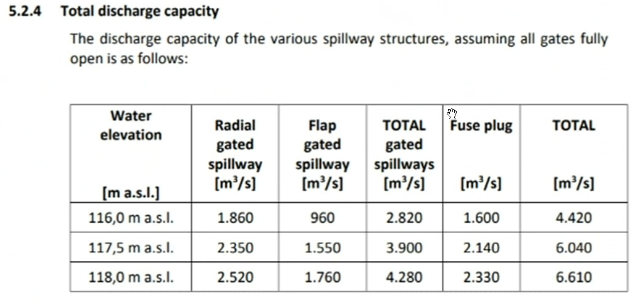

Mynd 1: Engin loka biluð

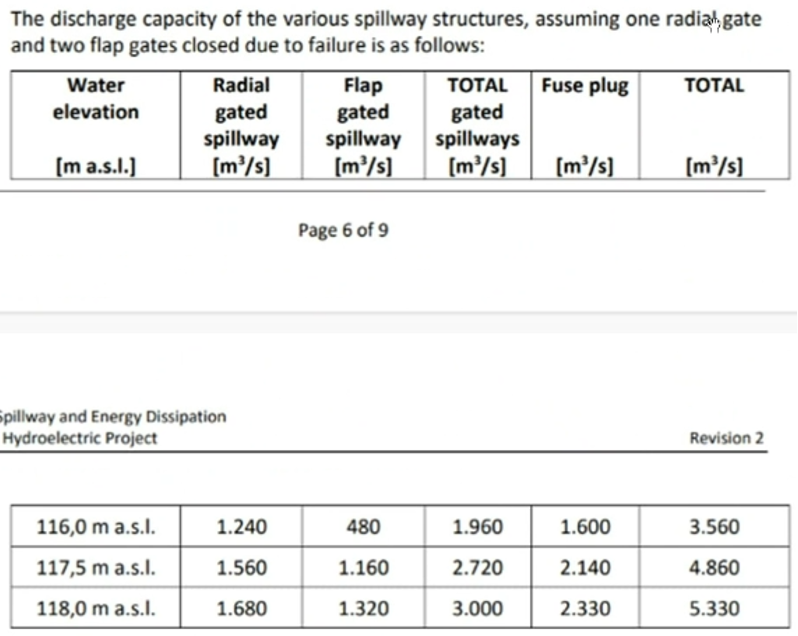

Mynd 2: Bilaðar lokur

1 geiraloka biluð

2 flipalokur bilaðar

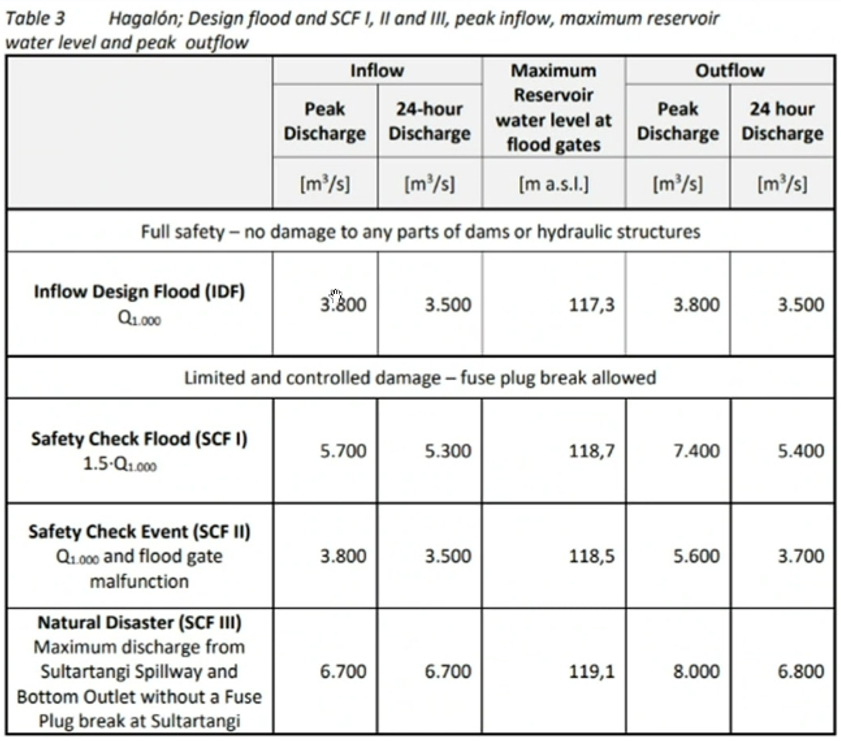

Mynd 3: Hámarksflæði miðað við öld eða eitthvað álíka.

- Vélar: 116,0 m.y.s.

- Seiðafleyta: 116,1

- Geiralokur: 116,2

- Flipalokur: 116,4

ATH: lokur feldar, á að loka aftur sjálfvirkt eða manual lokun?

- Flipaloka 1 felld: 116,4

- Flipaloka 2 felld: 116,5

- Flipaloka 3 felld: 116,6

- Flipaloka 4 felld: 116,7

Þröskuldar:

- Geiraloka: 107m

- Seiðaloka: 111m

- Op hjá seiðaloku: 114.8m

- Flipaloka: 112m

Þ.a. hæðir sem fara í formúlur m.v. hæð 116m a.s.l. eru:

- Geiraloka: $H_G = 116-107 = 9m$

- Seiðaloka: $H_S = 116-111 = 5m$

- Op hjá seiðaloku: $H_{op} = 116-114.8 = 1.2m$

- Flipalokur: $H_F=116-112=4m$

Frádráttur frá hæð lóns er því eftirfarandi (allar hæðir valdar út frá H fyrir geiralokur) 

- Hæð geiraloku er fyrst valið sem $H_G=H-9$ 

- Hæð seiðaloku er þar af leiðandi valin sem $H_{Sei}=H_G-(9-(116-111))=H_G-4$

- Hæð ops hjá seiðaloku er valið sem $H_{Op}=H_G-(9-(116-114.8))=H_G-7.8$

- Hæð flipaloku er valið sem $H_F = H_G-(9-(116-112))=H_G-5$

# Simulation Time and initialization

clear all; close all; clc;
addpath('Functions\')
% addpath('Tables\');

% Lesa inn skrá sem inniheldur innflæði í lón
% FileName = "Qin_new_8Days_Flod_saved";
% FileName = "Qin_new_2Days_Flod_saved";
% FileName = "Qin_new_2Days_Flod2_saved";
% FileName = "Qin_new_2Days_sveifla2_saved";
% FileName = "Qin_new_90Days_saved";
% FileName = "Qin_new_1Year_Handmade_saved";
% FileName = "Qin_new_8months_saved";
% FileName = "Qin_new_3months_saved";
FileName = "Qin_new_8Day_Flod_saved";

FileType = ".txt";
QinName  = append(FileName,FileType)

QinName = "Qin_new_1Day_saved.txt"


QinTable = readtable(QinName);

% QinMat   = cell2mat(struct2cell(load(QinName)));
% QinMat = QinTable.Data

% Qin      = QinMat(1,:);
Qin = QinTable.Data';
TimeData = QinTable.Time;

% Sækja tímagögn til hermunar
% days    = 9;
days    = QinTable.Days(1);
hours   = 24;  minutes = 60;  seconds = 60;  freq    = 5;
dt      = QinTable.dt(1);
% xLokaG   = 1/60; % Loka opnast 1m/1min
xLokaG = 0.3/60; % Opnunarhraði geiraloku á mínútu
xLokaS = 0.3/60; % Opnunarhraði seiðaloku á mínútu
xLokaF = 0.5/60; % Helmingun á tíma sem tekur að loka flipalokum

[T_samples,T_samples_H,T_samples_D,Nsim,DsyniG,DsyniS,DsyniF] = get_TimeData(seconds,minutes,hours,days,xLokaG,xLokaS,xLokaF,dt); 

samplesF = 5.5/DsyniF;
samplesSeinkunF = samplesF/2;

% Qin     = get_inFlow(Nsim,QinName);
% samples = (t0:q_dt:Finaltime-q_dt); % [samples] sýnafylki (Sample instants)
% Nsim    = length(samples);          % Lengd sýnafylkis

H_lagoon_initial = 116;

[H_init_G,H_edge_G,C1,Dmax_G,Dmin_G,kp,ki,Ti]                           = get_GeiralokaData(H_lagoon_initial); % Ná í gögn fyrir geiraloku
[H_init_S,H_edge_S,C1_Sei,Dmax_S,Dmin_S,C2_Sei,kp_Sei,ki_Sei,Ti_Sei]    = get_SeidalokaData(H_lagoon_initial); % Ná í gögn fyrir seiðaloku
[H_init_F,H_edge_F,Bflip]                                               = get_FlipalokaData(H_lagoon_initial); % Ná í gögn fyrir flipaloku

Hd(1,1:Nsim)     = 116.2 - H_edge_G;  % [m] H desired (reference value)
Hd_Sei(1,1:Nsim) = 116.1 - H_edge_G;  % [m] H desired (reference value)

DmaxTotal = 3*Dmax_G;

flipOpen1 = false;   flipOpen2 = false;   flipOpen3 = false;   flipOpen4 = false;

# Simulation

% get_modelGeira
% get_modelSeida
% get_modelFlipa

% Model
H_dot(1,1:Nsim)     = 0;
H(1,1:Nsim)         = H_init_G;
Hflip1(1,1:Nsim)    = 0;
Hflip2(1,1:Nsim)    = 0;
Hflip3(1,1:Nsim)    = 0;
Hflip4(1,1:Nsim)    = 0;
D1(1,1:Nsim)        = Dmin_G;
D2(1,1:Nsim)        = Dmin_G;
D3(1,1:Nsim)        = Dmin_G;
D_Sei(1,1:Nsim)     = Dmin_S; % Seiðaloka
Cg1(1,1:Nsim)       = Cg_D(D1(1,1),Dmin_G,Dmax_G);
Cg2(1,1:Nsim)       = Cg_D(D2(1,1),Dmin_G,Dmax_G);
Cg3(1,1:Nsim)       = Cg_D(D3(1,1),Dmin_G,Dmax_G);
Cp_Sei(1,1:Nsim)    = Cp_D(D_Sei(1,1),Dmin_S,Dmax_S); % Seiðaloka (Muna að gera nýtt Cg_D)
A(1,1:Nsim)         = 3.8 * 1000^2;
Qout_gate1(1,1:Nsim)= 0;
Qout_gate1(1,1)= Cg1(1,1) * C1 * D1(1,1) * sqrt(2*H(1,1) - D1(1,1));
Qout_gate2(1,1:Nsim)= 0;
Qout_gate2(1,1)= Cg2(1,1) * C1 * D2(1,1) * sqrt(2*H(1,1) - D2(1,1));
Qout_gate3(1,1:Nsim)= 0;
Qout_gate3(1,1)= Cg3(1,1) * C1 * D3(1,1) * sqrt(2*H(1,1) - D3(1,1));
Qout_flip1(1,1:Nsim) = 0;
Qout_flip2(1,1:Nsim) = 0;
Qout_flip3(1,1:Nsim) = 0;
Qout_flip4(1,1:Nsim) = 0;
Qout_Sei(1,1:Nsim)  = 0;
Qout_Sei(1,1)       = Cp_Sei(1,1) * C1_Sei * D_Sei(1,1) * sqrt(2*H(1,1) - D_Sei(1,1));
Qout_gate(1,1:Nsim) = 0;
Qout_gate(1,1)      = Qout_gate1(1,1) + Qout_gate2(1,1) + Qout_gate3(1,1) + Qout_flip1(1,1) + Qout_flip2(1,1) + Qout_flip3(1,1) + Qout_flip4(1,1) + Qout_Sei(1,1);
Qout(1,1:Nsim)      = 0;

% PI
error(1,1:Nsim)     = H(1,1) - Hd(1,1);
P(1,1:Nsim)         = 0;
I(1,1:Nsim)         = 0;
u(1,1:Nsim)         = 0;
ie(1,1:Nsim)        = 0;
op(1,1:Nsim)        = 0;
u_per(1,1:Nsim)     = 0;
u_Slow(1,1:Nsim)    = 0;
u_old(1,1:Nsim)     = 0;

% P controller for the radial gate opening
error_gate1(1,1:Nsim)   = 0;
error_gate2(1,1:Nsim)   = 0;
error_gate3(1,1:Nsim)   = 0;
error_u(1,1:Nsim)       = 0;
error_uDB(1,1:Nsim)     = 0;
PI_P_gate(1,1:Nsim)     = 0;
PI_I_gate(1,1:Nsim)     = 0;
PI_u_gate(1,1:Nsim)     = 0;
u_sat_gate(1,1:Nsim)    = 0;

% Anti-Reset Windup switch coefficient
kc(1,1:Nsim)        = 1;
intWindup(1,1:Nsim) = 0;
kc_gate(1,1:Nsim)   = 1;

window_val(1,1:Nsim) = 0;

% Deadband á error
DB_Val            = 0.01;
DBerror(1,1:Nsim) = DB_Val;

% Low Pass Filter Gain
alpha = 0.9; % Velja skal alpha á bilinu "0 <= alpha < 1"

% Gæði loka
dS = 5; % Lengd fylkis sem notað er í gæði loku
Samples1(1,1:dS) = 0;
Samples2(1,1:dS) = 0;
Samples3(1,1:dS) = 0;
Samples4(1,1:dS) = 0;
LastSamples1(1,1:dS) = 0;
LastSamples2(1,1:dS) = 0;
LastSamples3(1,1:dS) = 0;
LastSamples4(1,1:dS) = 0;
LastCount1 = 0;
LastCount2 = 0;
LastCount3 = 0;
LastCount4 = 0;
D1minVal(1,1:Nsim) = 0;
D2minVal(1,1:Nsim) = 0;
D3minVal(1,1:Nsim) = 0;
D4minVal(1,1:Nsim) = 0;

% Seiðaloka og þröskuldur við seiðaloku
error_Sei(1,1:Nsim)     = H(1,1) - Hd_Sei(1,1);
P_Sei(1,1:Nsim)         = 0;
I_Sei(1,1:Nsim)         = 0;
u_Sei(1,1:Nsim)         = 0;
ie_Sei(1,1:Nsim)        = 0;
op_Sei(1,1:Nsim)        = 0;
u_per_Sei(1,1:Nsim)     = 0;
u_Slow_Sei(1,1:Nsim)    = 0;
u_old_Sei(1,1:Nsim)     = 0;
H_Sei(1,1:Nsim)         = 0;
H_Op(1,1:Nsim)          = 0;
DBerror_Sei(1,1:Nsim)   = DBerror(1,1);
error_u_Sei(1,1:Nsim)   = 0;
Qout_thres(1,1:Nsim)    = 0;    % Þröskuldur við seiðaloku
Qout_st(1,1:Nsim)       = 0;    % Minna gildið af flæði um þröskuld vs. seiðaloku
Hg_Sei(1,1:Nsim)        = 0;
xOpenS                  = false;

% Frádráttur véla frá Qin
% Qv_osk  = 352;          % Fasti. Óskgildi véla að jafnaði (á bilinu 0 - 352)
% Qv_raun(1,1:Nsim) = 0;  % Gildið sem vélarnar taka raunverulega, getur verið minna en óskgildið ef rennslið er minna sem er stóran hluta árs
% % Qspa = Qin    % Qspa er sama og Qin úr emaili. Þetta eru brúuðu hrágildisgögnin hér að neðan: Qin_new
% % Qin_raun      % Notum þetta fyrir rennsli í lón eftir að búið er að draga frá vélar
% % Qseida        % Rennsli um seiðafleytu, lágmark c.a. 10m^3/s
% Qin_new(1,1:Nsim) = 0;
m_velar = 352 / (116.1 - 114.8); % 114.8 er þröskuldur inntaks hjá seiðafl.
Qout_velar(1,1:Nsim) = 0;


Qvelar_testf(1,1:Nsim)  = 0;
Qvelar_Sw               = false;

% Flipalokur
countF1 = 0;  countF2 = 0;  countF3 = 0;  countF4 = 0;
simF1 = 0;    simF2 = 0;    simF3 = 0;    simF4 = 0;

% Gæðateljari
D1_count(1,1:Nsim) = 0;
D2_count(1,1:Nsim) = 0;
D3_count(1,1:Nsim) = 0;
Ds_count(1,1:Nsim) = 0;

for i = 1 : Nsim-1

%     if i>1
%         if Qin(1,i) < (Qv_osk + Qout_st(1,i-1))
%             Qv_raun(1,i) = Qin(1,i) - Qout_st(1,i);
%         elseif Qin(1,i) > (Qv_osk + Qout_st(1,i-1))
%             Qv_raun(1,i) = Qv_osk;
%             Qin_new(1,i) = Qin(1,i) - Qv_raun(1,i);
%         end
%     end
    
    error(1,i)      = H(1,i) - Hd(1,i);     % Geiraloka
    error_Sei(1,i)  = H(1,i) - Hd_Sei(1,i); % Seidaloka
    
    % PI update fyrir geiralokur
    if i>1
        [ie(1,i),P(1,i),I(1,i),u(1,i)] = get_PIDupdate(error(1,i),ie(1,i-1),dt,kp,ki,Ti,op(1,1),DmaxTotal,Dmin_G);
    elseif i == 1
        [ie(1,i),P(1,i),I(1,i),u(1,i)] = get_PIDupdate(error(1,i),ie(1,i),dt,kp,ki,Ti,op(1,1),DmaxTotal,Dmin_G);
    end

    % PI update fyrir seiðaloku
    if i>1
        [ie_Sei(1,i),P_Sei(1,i),I_Sei(1,i),u_Sei(1,i)] = get_PIDupdate(error_Sei(1,i),ie_Sei(1,i-1),dt,kp_Sei,ki_Sei,Ti_Sei,op_Sei(1,1),Dmax_S,Dmin_S);
    elseif i == 1
        [ie_Sei(1,i),P_Sei(1,i),I_Sei(1,i),u_Sei(1,i)] = get_PIDupdate(error_Sei(1,i),ie_Sei(1,i),dt,kp_Sei,ki_Sei,Ti_Sei,op_Sei(1,1),Dmax_S,Dmin_S);
    end

    % Error og DeadBand uppfærsla fyrir geiraloku
    if i>1
        [DBerror(1,i),error_u(1,i)] = get_DeadBandError(u(1,i),DmaxTotal,i,u_Slow(1,i-1),DB_Val);    
    else
        [DBerror(1,i),error_u(1,i)] = get_DeadBandError(u(1,i),DmaxTotal,i,u_Slow(1,i),DB_Val);      
    end

    % Error og DeadBand uppfærsla fyrir seiðaloku
    if i>1
        [DBerror_Sei(1,i),error_u_Sei(1,i)] = get_DeadBandError(u_Sei(1,i),Dmax_S,i,u_Slow_Sei(1,i-1),DB_Val); 
    else
        [DBerror_Sei(1,i),error_u_Sei(1,i)] = get_DeadBandError(u_Sei(1,i),Dmax_S,i,u_Slow_Sei(1,i),DB_Val);   
    end


    % Geiraloka
    if i>1
        if error_u(1,i) > DBerror(1,i)
            u_Slow(1,i) = u_Slow(1,i-1) + DsyniG;
        elseif error_u(1,i) < -DBerror(1,i)
            u_Slow(1,i) = u_Slow(1,i-1) - DsyniG;
        else
            u_Slow(1,i) = u_Slow(1,i-1);
        end
    else
        if u(1,i) > 0
            u_Slow(1,i) = DsyniG;
        elseif u(1,i) < 0
            u_Slow(1,i) = DsyniG;
        else
            u_Slow(1,i) = u_Slow(1,1);
        end
    end

    % Seiðaloka
    if i>1
        if error_u_Sei(1,i) > DBerror_Sei(1,i)
            u_Slow_Sei(1,i) = u_Slow_Sei(1,i-1) + DsyniS;
        elseif error_u_Sei(1,i) < -DBerror_Sei(1,i)
            u_Slow_Sei(1,i) = u_Slow_Sei(1,i-1) - DsyniS;
        else
            u_Slow_Sei(1,i) = u_Slow_Sei(1,i-1);
        end
    else
        if u_Sei(1,i) > 0
            u_Slow_Sei(1,i) = DsyniS;
        elseif u_Sei(1,i) < 0
            u_Slow_Sei(1,i) = DsyniS;
        else
            u_Slow_Sei(1,i) = u_Slow_Sei(1,1);
        end
    end


    % Geiraloka + Controller output in percents
    u_per(1,i) = ControllerPercent(u_Slow(1,i),DmaxTotal,Dmin_G);
    %[D1(1,i),D2(1,i),D3(1,i)] = AnalogOpening2(u_per(1,i),DmaxTotal);
    [D1(1,i),D2(1,i),D3(1,i)] = AnalogOpening90(u_per(1,i),DmaxTotal);

    % Seiðaloka
%     if TimeData(i).Month == 7 % Seiðatímabil, þá er seiðaloka fullopin
%     if i >= 128000 && i <= 700000 % Seiðaloka föst fullopin á þessu tímabili.
%     if i >= 26784001 && i <= 52704000 % Seiðaloka föst fullopin á þessu tímabili.
    if i > Nsim % Notað til að afvirkja festingu á seiðaloku
        D_Sei(1,i) = Dmax_S;
    else
        D_Sei(1,i) = OpeningSei(u_Slow_Sei(1,i),Dmax_S,Dmin_S);
    end
    
    % Actuator quality
%     [D1_count,Samples1] = ActuatorQuality(D1(1,i),LastSamples1,LastCount1,i,4);
%     [D2_count,Samples2] = ActuatorQuality(D2(1,i),LastSamples2,LastCount2,i,4);
%     [D3_count,Samples3] = ActuatorQuality(D3(1,i),LastSamples3,LastCount3,i,4);
%     [D4_count,Samples4] = ActuatorQuality(D_Sei(1,i),LastSamples4,LastCount4,i,4);
% 
%     LastSamples1 = Samples1;
%     LastSamples2 = Samples2;
%     LastSamples3 = Samples3;
%     LastSamples4 = Samples4;
%     LastCount1 = D1_count;
%     LastCount2 = D2_count;
%     LastCount3 = D3_count;
%     LastCount4 = D4_count;

    if i > 2
%         [D1_count,D1_quality] = ActuatorQuality2(D1(1,i),D1(1,i-2),i,D1_count,Nsim);
%         [D1_count,D1_count_i,D1_quality] = ActuatorQuality2(D1(1,i),D1(1,i-1),i,D1_count,D1_count_i,D1_quality,Nsim);
        [D1_count(1,i),D1_count_i,D1_quality] = ActuatorQuality(D1(1,i),D1(1,i-1),i,D1_count(1,i-1),D1_count_i,D1_quality,Nsim,DsyniG,0.00001);
    else
        D1_count(1,i) = 0;
        D1_count_i = 0;
        D1_quality = 0;
    end
    if i > 2
%         [D2_count,D2_quality] = ActuatorQuality2(D2(1,i),D2(1,i-2),i,D2_count,Nsim);
        [D2_count(1,i),D2_count_i,D2_quality] = ActuatorQuality(D2(1,i),D2(1,i-1),i,D2_count(1,i-1),D2_count_i,D2_quality,Nsim,DsyniG,0.00001);
    else
        D2_count(1,i) = 0;
        D2_count_i = 0;
        D2_quality = 0;
    end
    if i > 2
%         [D3_count,D3_quality] = ActuatorQuality2(D3(1,i),D3(1,i-2),i,D3_count,Nsim);
        [D3_count(1,i),D3_count_i,D3_quality] = ActuatorQuality(D3(1,i),D3(1,i-1),i,D3_count(1,i-1),D3_count_i,D3_quality,Nsim,DsyniG,0.00001);    
    else
        D3_count(1,i) = 0;
        D3_count_i = 0;
        D3_quality = 0;
    end
    if i > 2
%         [Ds_count,Ds_quality] = ActuatorQuality2(D_Sei(1,i),D_Sei(1,i-2),i,Ds_count,Nsim);
        [Ds_count(1,i),Ds_count_i,Ds_quality] = ActuatorQuality(D_Sei(1,i),D_Sei(1,i-1),i,Ds_count(1,i-1),Ds_count_i,Ds_quality,Nsim,DsyniS,0.00001);
    else
        Ds_count(1,i) = 0;
        Ds_count_i = 0;
        Ds_quality = 0;
    end

    Cg1(1,i)     = Cg_D(D1(1,i),Dmin_G,Dmax_G);
    Cg2(1,i)     = Cg_D(D2(1,i),Dmin_G,Dmax_G);
    Cg3(1,i)     = Cg_D(D3(1,i),Dmin_G,Dmax_G);
    Cp_Sei(1,i)  = Cp_D(D_Sei(1,i),Dmin_S,Dmax_S); 
%     Cg1(1,i)     = 0.7;

    Hflip1(1,i) = H(1,i) - 5; % Hæð f. flipaloku
    Hflip2(1,i) = H(1,i) - 5; % Hæð f. flipaloku
    Hflip3(1,i) = H(1,i) - 5; % Hæð f. flipaloku
    Hflip4(1,i) = H(1,i) - 5; % Hæð f. flipaloku
    H_Op(1,i)   = H(1,i) - 7.8; % Hæð f. Op hjá seiðaloku
    H_Sei(1,i)  = H(1,i) - 4 - 0.25; % Hæð f. Seiðaloku
%     H_Sei(1,i)  = H_Op(1,i) - 0.25; % Hæð f. Seiðaloku
    if H(1,i) < 0
        H(1,i) = 0;
    end
    if Hflip1(1,i) < 0
        Hflip1(1,i) = 0;
    end
    if Hflip2(1,i) < 0
        Hflip2(1,i) = 0;
    end
    if Hflip3(1,i) < 0
        Hflip3(1,i) = 0;
    end
    if Hflip4(1,i) < 0
        Hflip4(1,i) = 0;
    end
    if H_Sei(1,i) < 0
        H_Sei(1,i) = 0;
    end
    if H_Op(1,i) < 0
        H_Op(1,i) = 0;
    end

    % Geiraloka
    Qout_gate1(1,i)  = Cg1(1,i) * C1 * D1(1,i) * sqrt(2*H(1,i) - D1(1,i));
    Qout_gate2(1,i)  = Cg2(1,i) * C1 * D2(1,i) * sqrt(2*H(1,i) - D2(1,i));
    Qout_gate3(1,i)  = Cg3(1,i) * C1 * D3(1,i) * sqrt(2*H(1,i) - D3(1,i));
    
    % Seiðaloka
    HDsei = 2*H_Sei(1,i) - D_Sei(1,i);
    if HDsei < 0
        HDsei = 0;
    end

     
    Qout_Sei(1,i)    = Cp_Sei(1,i) * C1_Sei * D_Sei(1,i) * sqrt(HDsei);
    Hg_Sei(1,i)      = H_Sei(1,i) + (D_Sei(1,i)/2);

    if Qout_Sei(1,i) < 0
        Qout_Sei(1,i) = 0;
    end
    
    % Þröskuldur við seiðaloku
    Qout_thres(1,i) = C2_Sei*((H_Op(1,i))^(1.5));

    
    if Qout_Sei(1,i) < Qout_thres(1,i)
        Qout_st(1,i) = Qout_Sei(1,i);
    else
        Qout_st(1,i) = Qout_thres(1,i);
    end

%     if H(1,i) <= H_initial_flip | flipOpen
    if H(1,i) >= 9.4 || flipOpen1 % Flipaloka fellur í 116.4, þ.e. 116.4-107=9.4
        countF1 = countF1 + 1;
        if countF1 > samplesSeinkunF
            Qout_flip1(1,i)   = 1.8*(Hflip1(1,i))^(1.5)*Bflip;
        end
        if flipOpen1 == false
            simF1 = i;
        end
        flipOpen1 = true;
    end
    if H(1,i) >= 9.5 || flipOpen2 
        countF2 = countF2 + 1;
        if countF2 > samplesSeinkunF
            Qout_flip2(1,i)   = 1.8*(Hflip2(1,i))^(1.5)*Bflip;
        end
        if flipOpen2 == false
            simF2 = i;
        end
        flipOpen2 = true;
    end
    if H(1,i) >= 9.6 || flipOpen3
        countF3 = countF3 + 1;
        if countF3 > samplesSeinkunF
            Qout_flip3(1,i)   = 1.8*(Hflip3(1,i))^(1.5)*Bflip;
        end
        if flipOpen3 == false
            simF3 = i;
        end
        flipOpen3 = true;
    end
    if H(1,i) >= 9.7 || flipOpen4 
        countF4 = countF4 + 1;
        if countF4 > samplesSeinkunF
            Qout_flip4(1,i)   = 1.8*(Hflip4(1,i))^(1.5)*Bflip;
        end
        if flipOpen4 == false
            simF4 = i;
        end
        flipOpen4 = true;
    end
    

%     if i >= 728000 && i <= 1100000 % Stilling á útslætti véla. Þegar Qvelar_Sw er true þá er rennsli = 0 um vélar.
    if i > Nsim % Notað til að útiloka að útsláttur véla virkjist, þ.a. Qvelar_Sw er alltaf false
%     if i>= 0435195
        Qvelar_Sw = true;
    else
        Qvelar_Sw = false;
    end

    if Qvelar_Sw == false 
        Qout_velar(1,i) = Qvelar(H(1,i),m_velar);
    else
        Qout_velar(1,i) = 0;
    end
%     Qvelar_testf(1,i) = m_velar*((107+H(1,i))-114.8);

    Qout(1,i)        = Qout_gate1(1,i) + Qout_gate2(1,i) + Qout_gate3(1,i) + Qout_flip1(1,i) ...
                     + Qout_flip2(1,i) + Qout_flip3(1,i) + Qout_flip4(1,i) + Qout_st(1,i) + Qout_velar(1,i);
%     Qout(1,i)        = Qout_flip(1,i);

%   Qvelar =

    H_dot(1,i)       = (1/A(1,i)) * (Qin(1,i) - Qout(1,i));
%     H(1,i+1)         = H(1,i) + 0.5 * (H_dot(1,i) + H_dot(1,i+1)) * dt;
%     H(1,i+1)         = H(1,i) + H_dot(1,i) * dt;
    
    if i>1
        H(1,i+1)         = H(1,i-1) + 0.5 * (H_dot(1,i) + H_dot(1,i-1)) * dt;
    else
        H(1,i+1)         = H(1,i) + H_dot(1,i) * dt;
    end
%     A(1,i+1) = AreaReservoir(H(1,i+1));

end

error(1,i+1) = H(1,i+1) - Hd(1,i+1);
error_Sei(1,i+1)  = H(1,i+1) - Hd_Sei(1,i+1); % Seidaloka

[ie(1,i+1),P(1,i+1),I(1,i+1),u(1,i+1)] = get_PIDupdate(error(1,i+1),ie(1,i),dt,kp,ki,Ti,op(1,1+1),DmaxTotal,Dmin_G);
[ie_Sei(1,i+1),P_Sei(1,i+1),I_Sei(1,i+1),u_Sei(1,i+1)] = get_PIDupdate(error_Sei(1,i+1),ie_Sei(1,i),dt,kp_Sei,ki_Sei,Ti_Sei,op_Sei(1,1+1),Dmax_S,Dmin_S);

[DBerror(1,i+1),error_u(1,i+1)] = get_DeadBandError(u(1,i+1),DmaxTotal,i,u_Slow(1,i),DB_Val);  
[DBerror_Sei(1,i+1),error_u_Sei(1,i+1)] = get_DeadBandError(u(1,i+1),Dmax_S,i,u_Slow_Sei(1,i),DB_Val);

        if error_u(1,i+1) > DBerror(1,i+1)
            u_Slow(1,i+1) = u_Slow(1,i) + DsyniG;
        elseif error_u(1,i+1) < -DBerror(1,i+1)
            u_Slow(1,i+1) = u_Slow(1,i) - DsyniG;
        else
            u_Slow(1,i+1) = u_Slow(1,i);
        end

        if error_u_Sei(1,i+1) > DBerror_Sei(1,i+1)
            u_Slow_Sei(1,i+1) = u_Slow_Sei(1,i) + DsyniS;
        elseif error_u_Sei(1,i+1) < -DBerror_Sei(1,i+1)
            u_Slow_Sei(1,i+1) = u_Slow_Sei(1,i) - DsyniS;
        else
            u_Slow_Sei(1,i+1) = u_Slow_Sei(1,i);
        end

u_per(1,i+1) = ControllerPercent(u_Slow(1,i+1),DmaxTotal,Dmin_G);
[D1(1,i+1),D2(1,i+1),D3(1,i+1)] = AnalogOpening2(u_per(1,i+1),DmaxTotal);
D_Sei(1,i+1) = OpeningSei(u_Slow_Sei(1,i+1),Dmax_S,Dmin_S);

Cg1(1,i+1)     = Cg_D(D1(1,i+1),Dmin_G,Dmax_G);
Cg2(1,i+1)     = Cg_D(D2(1,i+1),Dmin_G,Dmax_G);
Cg3(1,i+1)     = Cg_D(D3(1,i+1),Dmin_G,Dmax_G);
Cp_Sei(1,i+1)  = Cp_D(D_Sei(1,i+1),Dmin_S,Dmax_S); 

Hflip1(1,i+1) = H(1,i+1) - 5; % Hæð f. flipaloku
Hflip2(1,i+1) = H(1,i+1) - 5; % Hæð f. flipaloku
Hflip3(1,i+1) = H(1,i+1) - 5; % Hæð f. flipaloku
Hflip4(1,i+1) = H(1,i+1) - 5; % Hæð f. flipaloku
H_Op(1,i+1)   = H(1,i+1) - 7.8; % Hæð f. Op hjá seiðaloku
H_Sei(1,i+1)  = H(1,i+1) - 4 - 0.25; % Hæð f. Seiðaloku

if H(1,i+1) < 0
    H(1,i+1) = 0;
end
if Hflip1(1,i+1) < 0
    Hflip1(1,i+1) = 0;
end
if Hflip2(1,i+1) < 0
    Hflip2(1,i+1) = 0;
end
if Hflip3(1,i+1) < 0
    Hflip3(1,i+1) = 0;
end
if Hflip4(1,i+1) < 0
    Hflip4(1,i+1) = 0;
end
if H_Sei(1,i+1) < 0
    H_Sei(1,i+1) = 0;
end
if H_Op(1,i+1) < 0
    H_Op(1,i+1) = 0;
end

% Geiraloka
Qout_gate1(1,i+1)  = Cg1(1,i+1) * C1 * D1(1,i+1) * sqrt(2*H(1,i+1) - D1(1,i+1));
Qout_gate2(1,i+1)  = Cg2(1,i+1) * C1 * D2(1,i+1) * sqrt(2*H(1,i+1) - D2(1,i+1));
Qout_gate3(1,i+1)  = Cg3(1,i+1) * C1 * D3(1,i+1) * sqrt(2*H(1,i+1) - D3(1,i+1));
    
% Seiðaloka
HDsei = 2*H_Sei(1,i+1) - D_Sei(1,i+1);
if HDsei < 0
    HDsei = 0;
end
Qout_Sei(1,i+1)    = Cp_Sei(1,i+1) * C1_Sei * D_Sei(1,i+1) * sqrt(HDsei);
Hg_Sei(1,i+1)      = H_Sei(1,i+1) + (D_Sei(1,i+1)/2);

if Qout_Sei(1,i+1) < 0
    Qout_Sei(1,i+1) = 0;
end

% Þröskuldur við seiðaloku
Qout_thres(1,i+1) = C2_Sei*((H_Op(1,i+1))^(1.5));

if Qout_Sei(1,i+1) < Qout_thres(1,i+1)
    Qout_st(1,i+1) = Qout_Sei(1,i+1);
else
    Qout_st(1,i+1) = Qout_thres(1,i+1);
end

if H(1,i+1) >= 9.4 || flipOpen1 % Flipaloka fellur í 116.4, þ.e. 116.4-107=9.4
    Qout_flip1(1,i+1)   = 1.8*(Hflip1(1,i+1))^(1.5)*Bflip;
    flipOpen1 = true;
end
if H(1,i+1) >= 9.5 || flipOpen2 
    Qout_flip2(1,i+1)   = 1.8*(Hflip2(1,i+1))^(1.5)*Bflip;
    flipOpen2 = true;
end
if H(1,i+1) >= 9.6 || flipOpen3 
    Qout_flip3(1,i+1)   = 1.8*(Hflip3(1,i+1))^(1.5)*Bflip;
    flipOpen3 = true;
end
if H(1,i+1) >= 9.7 || flipOpen4 
    Qout_flip4(1,i+1)   = 1.8*(Hflip4(1,i+1))^(1.5)*Bflip;
    flipOpen4 = true;
end

Qout_velar(1,i+1) = Qvelar(H(1,i+1),m_velar);

Qout(1,i+1)        = Qout_gate1(1,i+1) + Qout_gate2(1,i+1) + Qout_gate3(1,i+1) + Qout_flip1(1,i+1) ...
                 + Qout_flip2(1,i+1) + Qout_flip3(1,i+1) + Qout_flip4(1,i+1) + Qout_st(1,i+1) + Qout_velar(1,i+1);

H_dot(1,i+1)       = (1/A(1,i+1)) * (Qin(1,i+1) - Qout(1,i+1));

% Gæði loku
CountArray = [D1_count D1_count_i D1_quality; D2_count D2_count_i D2_quality; D3_count D3_count_i D3_quality; Ds_count Ds_count_i Ds_quality];
% CountArray = [D1_count D1_count_i D1_quality];
% CountArray = [Ds_count Ds_count_i Ds_quality];

disp('Geiraloka 1')

Geiraloka 1


sprintf('%f', D1_quality)

ans = '0.000000'

disp('Geiraloka 2')

Geiraloka 2


sprintf('%f', D2_quality)

ans = '0.000000'

disp('Geiraloka 3')

Geiraloka 3


sprintf('%f', D3_quality)

ans = '0.000000'

disp('Seiðaloka')

Seiðaloka


sprintf('%f', Ds_quality)

ans = '0.479282'

# Plot

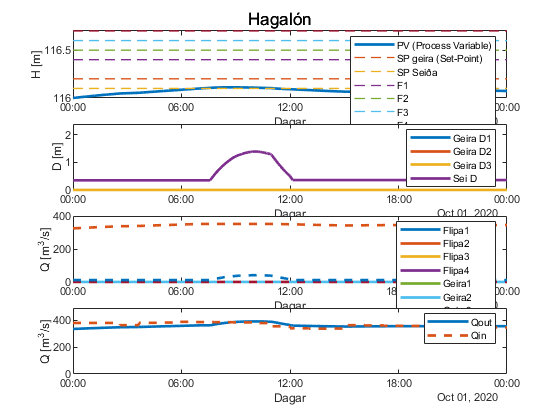

% XaxisScaled = T_samples/(T_samples_D/10); % 9 dagar
% 
% xaxisLdays = 0;
% if xaxisLdays == 0
%     xaxisLimit = 1;
% else
%     xaxisLimit = (length(XaxisScaled)/9)*(xaxisLdays);
% end


% XaxisScaled = T_samples/(T_samples_H); % 9*24 hours dagar

close all;
figure; % Change of height
sgtitle('Hagalón')
subplot(4,1,1)
plot(TimeData,H + H_edge_G,"LineWidth",2); hold on;
plot(TimeData,Hd + H_edge_G,"--","LineWidth",1); hold on;
plot(TimeData,Hd_Sei + H_edge_G,"--","LineWidth",1); hold on;
plot(TimeData,9.4*ones(1,Nsim) + H_edge_G,"--","LineWidth",1); hold on;
plot(TimeData,9.5*ones(1,Nsim) + H_edge_G,"--","LineWidth",1); hold on;
plot(TimeData,9.6*ones(1,Nsim) + H_edge_G,"--","LineWidth",1); hold on;
plot(TimeData,9.7*ones(1,Nsim) + H_edge_G,"--","LineWidth",1);
% plot(T_samples,H + H_edge_G,"LineWidth",2); hold on;
% plot(T_samples,Hd + H_edge_G,"--","LineWidth",2);
% set(gca,'XTick',1:XaxisScaled(2):length(XaxisScaled));
% set(gca,'XTickLabel',1:1:216);
legend("PV (Process Variable)","SP geira (Set-Point)", "SP Seiða", "F1", "F2", "F3", "F4");
ylabel('H [m]'); xlabel('Dagar');
% xlim([t0 t_f]); grid;
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
% ax = gca;
% ax.XTick = 1:1:T_samples;
% ax.XTickLabel = 1:1:9;
% ax.XAxis.Exponent = 0;

% ylim([0 120]); grid;
subplot(4,1,2)
plot(TimeData,D1,"LineWidth",2); hold on;
plot(TimeData,D2,"LineWidth",2); hold on;
plot(TimeData,D3,"LineWidth",2); hold on;
plot(TimeData,D_Sei,"LineWidth",2); hold on;
% xline(TimeData(238936),'-',{'238936'}); hold on;
% xline(TimeData(321390),'-',{'321390'}); hold on;
% xline(TimeData(373646),'-',{'373646'}); hold on;
% xline(TimeData(401517),'-',{'401517'}); hold on;
legend('Geira D1','Geira D2','Geira D3', 'Sei D');
ylabel('D [m]'); xlabel('Dagar');
ylim([0 (max(max(D1),max(D_Sei))+1)]);


% xlim([t0 t_f]); grid;
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
% ax = gca;
% ax.XAxis.Exponent = 0;
% ax.XTick = 0:T_samples_D:T_samples;
% ax.XTickLabel = 0:1:9;
subplot(4,1,3)
plot(TimeData,Qout_flip1,"LineWidth",2); hold on;
plot(TimeData,Qout_flip2,"LineWidth",2); hold on;
plot(TimeData,Qout_flip3,"LineWidth",2); hold on;
plot(TimeData,Qout_flip4,"LineWidth",2); hold on;
plot(TimeData,Qout_gate1,"LineWidth",2); hold on;
plot(TimeData,Qout_gate2,"LineWidth",2); hold on;
plot(TimeData,Qout_gate3,"--","LineWidth",2); hold on;
plot(TimeData,Qout_st,"--","LineWidth",2); hold on;
plot(TimeData,Qout_velar,"--","LineWidth",2); hold on; 
if flipOpen1 == true
    xline(TimeData(simF1),'-',{'F1start'}); hold on;
end
if flipOpen2 == true
    xline(TimeData(simF2),'-',{'F2start'}); hold on;
end
if flipOpen3 == true
    xline(TimeData(simF3),'-',{'F3start'}); hold on;
end
if flipOpen4 == true
    xline(TimeData(simF4),'-',{'F4start'}); hold on;
end
ylabel('Q [m^3/s]'); xlabel('Dagar');
% xlim([t0 t_f]); ylim([0 700]); grid;
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
legend('Flipa1','Flipa2','Flipa3','Flipa4','Geira1','Geira2','Geira3','Seiðal + op', 'Vélar');
% ax = gca;
% ax.XTick = 0:T_samples_D:T_samples;
% ax.XTickLabel = 0:1:9;
subplot(4,1,4)
plot(TimeData,Qout,"LineWidth",2); hold on;
plot(TimeData,Qin,"--","LineWidth",2);
ylabel('Q [m^3/s]'); xlabel('Dagar');
ylim([0 (max(Qout)+100)]); 
% xlim([t0 t_f]); grid;
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
legend("Qout", "Qin");
% ax = gca;
% ax.XTick = 0:T_samples_D:T_samples;
% ax.XTickLabel = 0:1:9;

uicontrol('Visible','off')

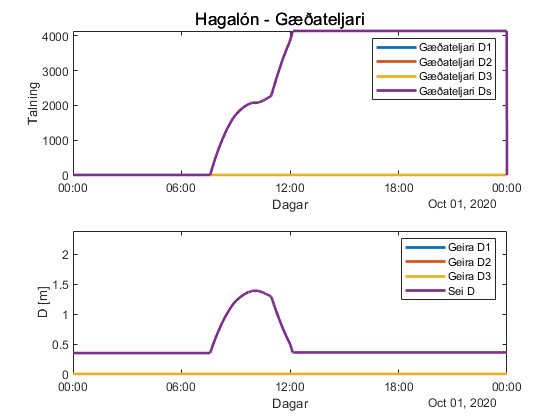

figure; % Change of height
sgtitle('Hagalón - Gæðateljari')
subplot(2,1,1)
plot(TimeData,D1_count,"LineWidth",2); hold on;
plot(TimeData,D2_count,"LineWidth",2); hold on;
plot(TimeData,D3_count,"LineWidth",2); hold on;
plot(TimeData,Ds_count,"LineWidth",2); hold on;
legend("Gæðateljari D1","Gæðateljari D2","Gæðateljari D3","Gæðateljari Ds");
ylabel('Talning'); xlabel('Dagar');


% ylim([0 120]); grid;
subplot(2,1,2)
plot(TimeData,D1,"LineWidth",2); hold on;
plot(TimeData,D2,"LineWidth",2); hold on;
plot(TimeData,D3,"LineWidth",2); hold on;
plot(TimeData,D_Sei,"LineWidth",2); hold on;
% xline(TimeData(238936),'-',{'238936'}); hold on;
% xline(TimeData(321390),'-',{'321390'}); hold on;
% xline(TimeData(373646),'-',{'373646'}); hold on;
% xline(TimeData(401517),'-',{'401517'}); hold on;
legend('Geira D1','Geira D2','Geira D3', 'Sei D');
ylabel('D [m]'); xlabel('Dagar');
ylim([0 (max(max(D1),max(D_Sei))+1)]);

uicontrol('Visible','off')

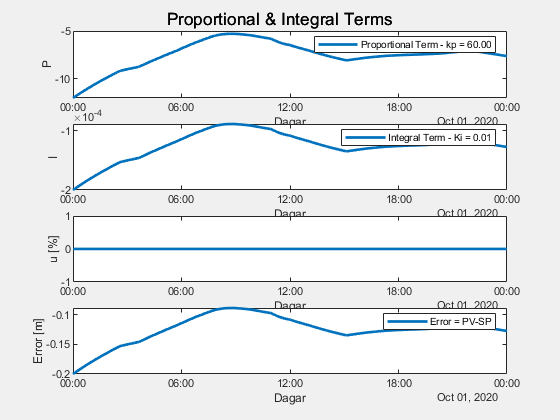

figure; % Change of height
sgtitle('Proportional & Integral Terms')
subplot(4,1,1)
plot(TimeData,P,"LineWidth",2);
ylabel('P'); xlabel('Dagar');
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
comment_1 = sprintf("Proportional Term - kp = %.2f",kp);
legend(comment_1)
subplot(4,1,2)
plot(TimeData,I,"LineWidth",2);
ylabel('I'); xlabel('Dagar');
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
comment_2 = sprintf("Integral Term - Ki = %.2f",ki);   
legend(comment_2)
subplot(4,1,3)
plot(TimeData,u_per,"LineWidth",2);
ylabel('u [%]'); xlabel('Dagar');
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
% comment_2 = sprintf("Integral Term - Ki = %.2f",ki);   
% legend(comment_2)
subplot(4,1,4)
plot(TimeData,error,"LineWidth",2);
ylabel('Error [m]'); xlabel('Dagar');
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
legend('Error = PV-SP');
% saveas(gcf,"fig_fundur.fig");

uicontrol('Visible','off');

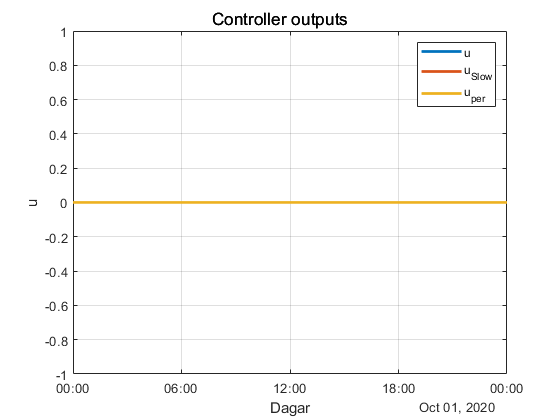

figure; % Change of height
sgtitle('Controller outputs');
plot(TimeData,u,"LineWidth",2); hold on;
plot(TimeData,u_Slow,"LineWidth",2); hold on;
plot(TimeData,u_per,"LineWidth",2);
ylabel('u'); xlabel('Dagar');
legend('u','u_{Slow}','u_{per}');
grid;
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); 

uicontrol('Visible','off');

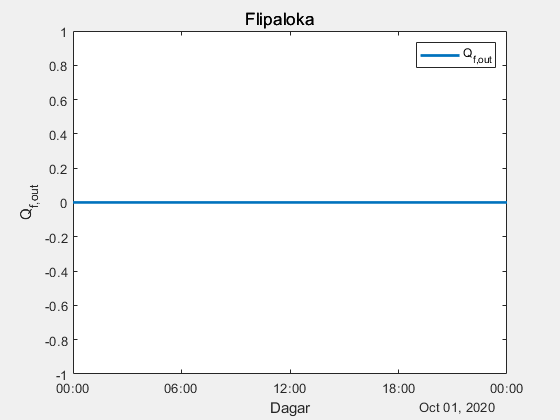

figure; % Change of height
sgtitle('Flipaloka');
plot(TimeData,Qout_flip1,"LineWidth",2);
ylabel('Q_{f,out}'); xlabel('Dagar');
legend('Q_{f,out}');
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;

uicontrol('Visible','off');

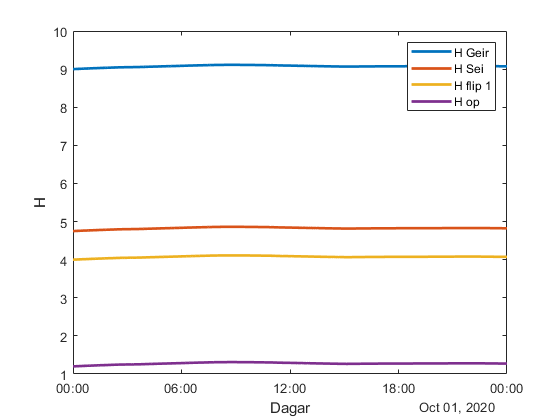

figure; % Hæðir
plot(TimeData,H,"LineWidth",2); hold on; 
plot(TimeData,H_Sei,"LineWidth",2); hold on; 
plot(TimeData,Hflip1,"LineWidth",2); hold on;
plot(TimeData,H_Op,"LineWidth",2);
ylabel('H'); xlabel('Dagar');
legend('H Geir', 'H Sei', 'H flip 1','H op');

uicontrol('Visible','off');

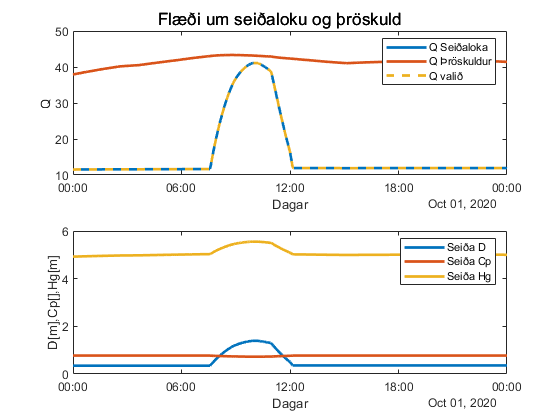

figure; % Change of height
sgtitle('Flæði um seiðaloku og þröskuld');
subplot(2,1,1)
plot(TimeData,Qout_Sei,"LineWidth",2); hold on;
plot(TimeData,Qout_thres,"LineWidth",2); hold on;
plot(TimeData,Qout_st,"--","LineWidth",2);
ylabel('Q'); xlabel('Dagar');
legend('Q Seiðaloka','Q Þröskuldur','Q valið');
% xlim([XaxisScaled(xaxisLimit) XaxisScaled(end)]); grid;
subplot(2,1,2)
plot(TimeData,D_Sei,"LineWidth",2); hold on;
plot(TimeData,Cp_Sei,"LineWidth",2); hold on;
plot(TimeData,Hg_Sei,"LineWidth",2); 
ylabel('D[m],Cp[],Hg[m]'); xlabel('Dagar');
legend('Seiða D','Seiða Cp','Seiða Hg');

uicontrol('Visible','off');

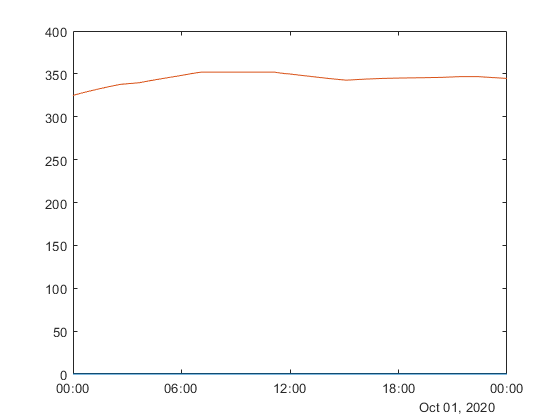

figure;
plot(TimeData,Qvelar_testf); hold on;
plot(TimeData,Qout_velar);

uicontrol('Visible','off');